# SPS Atlas

## Load *D.melanogaster* genome

clear all; close all; clc;
dmel = {};
dmel.X = getgenbank('NC_004354','SequenceOnly',true);
%dmel.Y = getgenbank('NC_024512','SequenceOnly',true);
dmel.twoL = getgenbank('NT_033779','SequenceOnly',true);
dmel.twoR = getgenbank('NT_033778','SequenceOnly',true);
dmel.threeL = getgenbank('NT_037436','SequenceOnly',true);
dmel.threeR = getgenbank('NT_033777','SequenceOnly',true);
dmel.four = getgenbank('NC_024512','SequenceOnly',true);

## Load *D.simulans* genome

dsim = {};
dsim.X = getgenbank('NC_029795','SequenceOnly',true);
dsim.twoL = getgenbank('NT_479533','SequenceOnly',true);
dsim.twoR = getgenbank('NT_479534','SequenceOnly',true);
dsim.threeL = getgenbank('NT_479535','SequenceOnly',true);
dsim.threeR = getgenbank('NT_479536','SequenceOnly',true);
dsim.four = getgenbank('NC_029796','SequenceOnly',true);

## Load *D.yakuba* genome

dyak = {};
dyak.X = getgenbank('NC_011091','SequenceOnly',true);
dyak.twoL = getgenbank('NT_167062','SequenceOnly',true);
dyak.twoR = getgenbank('NT_167063','SequenceOnly',true);
dyak.threeL = getgenbank('NT_167064','SequenceOnly',true);
dyak.threeR = getgenbank('NT_167065','SequenceOnly',true);
dyak.four = getgenbank('NC_011090','SequenceOnly',true);

## Load SPS half-Motifs fwd

%ref SpDamID paper (Fig. 7)
SPS.a = upper(char('ggctggggg'));
SPS.b = upper(char('caggtgggaa'));
SPS.c = upper(char('taaaagggg'));
SPS.d = upper(char('aggatgagt'));
SPS.e = upper(char('aggcctggc'));

## Load SPS half-Motifs rev

SPS.f = seqrcomplement(SPS.a);
SPS.g = seqrcomplement(SPS.b);
SPS.h = seqrcomplement(SPS.c);
SPS.i = seqrcomplement(SPS.d);
SPS.j = seqrcomplement(SPS.e);

## Search Alg Brute

% k1 = strfind(dmel.X, SPS.a)
% k2 = strfind(dmel.X, SPS.b)
% k3 = strfind(dmel.X, SPS.c)
% k4 = strfind(dmel.X, SPS.d)
% k5 = strfind(dmel.X, SPS.e)
% 
% k6 = strfind(dmel.X, SPS.f)
% k7 = strfind(dmel.X, SPS.g)
% k8 = strfind(dmel.X, SPS.h)
% k9 = strfind(dmel.X, SPS.i)
% k10 = strfind(dmel.X, SPS.j)


## Search Alg Iterative

Sfields = fieldnames(SPS);
Dfields = fieldnames(dmel);
for i = 1:length(fieldnames(SPS));
    for j = 1:length(fieldnames(dmel))
        qq{:,1,j,i} = strfind(dmel.(Dfields{j}), SPS.(Sfields{i}))';
    end
end

% n = 2;
% fields = fieldnames(struc);
% struc.(fields{n})

## Group by Chromosome

ra = [];
rb = [];
rc = [];
rd = [];
re = [];
rf = [];

for i = 1:length(fieldnames(SPS));
    ra = [ra; qq{:,1,1,i}]; %dmel.X
    rb = [rb; qq{:,1,2,i}]; %dmel.twoL
    rc = [rc; qq{:,1,3,i}]; %dmel.twoR
    rd = [rd; qq{:,1,4,i}]; %dmel.threeL
    re = [re; qq{:,1,5,i}]; %dmel.threeR
    rf = [rf; qq{:,1,6,i}]; %dmel.four
end

rtot = length(ra) + length(rb) + length(rc) + length(rd) + length(re) + length(rf)

rtot = 3774

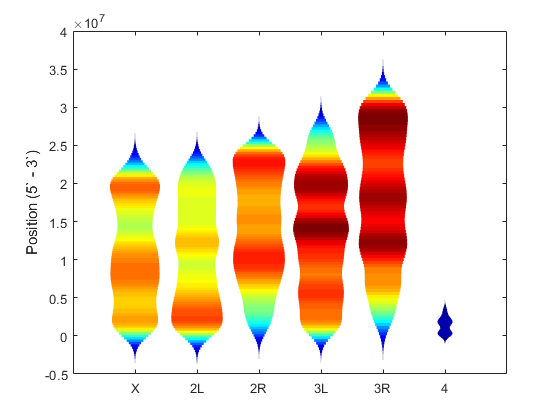


rad = ra/length(dmel.X);
rbd = rb/length(dmel.twoL);
rcd = rc/length(dmel.twoR);
rdd = rd/length(dmel.threeL);
red = re/length(dmel.threeR);
rfd = rf/length(dmel.four);

% figure, 
% scatter(ones(length(ra),1), rad, '.'); hold on;
% scatter(ones(length(rb),1)*2, rbd, '.');
% scatter(ones(length(rc),1)*3, rcd, '.');
% scatter(ones(length(rd),1)*4, rdd, '.');
% scatter(ones(length(re),1)*5, red, '.');
% scatter(ones(length(rf),1)*6, rfd, '.');
% xlim([0 7]);
% box on;


rall = {ra, rb, rc, rd, re, rf};
rnames = {'X', '2L', '2R', '3L', '3R', '4'};
figure,
distributionPlot(rall, 'showMM', 0, 'colormap', jet, 'globalNorm', 2, 'xNames', rnames); 
box on;
ylabel('Position (5` - 3`)')

% spsdmelx{:,:} = qq{:,:,1,:}

## SPS Location Store

% dmelSPS = {}
% dmelSPS.X = {k1, k2, k3, k4, k5}

## Load *D.sechellia* genome

% dsec = {};

## Load D.erecta genome

% dere = {};

## Load D.anasai genome

% dana = {};

## Load D.pseudoobscura genome

% dpse = {};

## Load D.persimilis genome

% dper = {};

## Load D.**willistoni** genome

% dwil = {};

## Load D.mojavensis genome

% dmoj = {};

## Load D.virilis genome

% dvir = {};